# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Données 

M1 = [A B C];%Matrice des coefficients de la fonction objectif pour la partie 1

%Vecteurs contenant les demandes en puissances (en MW) pour la partie 1: 
%On considère ici que les demandes ne peuvent pas être inférieures à la
%somme des puissances minimales des centrales (= on ne produit jamais d'énergie perdue),
%ni supérieures à la somme des puissances maximales des centrales (=on ne
%manque jamais d'énergie). Ces hypothèses ne paraissent pas réalistes,
%surtout la première, puisque les pays revendent le surplus d'énergie
%produits à leurs voisins.
Demandes1=linspace(sum(Pmin),sum(Pmax),10);


%Matrice des coefficients de la fonction objectif pour la partie 2.
%On passe les données présentées dans l'unité demandées (en heures) d'où la division par 24.
D1=D/24;
E1=E/24;
M2= [D1 E1 F];

%Demande de la partie 2, fixée à 400 MW.
Demandes2 = [400]; 

## Partie 1

    1.1 Définition de la fonction objectif

% variables : puissances fournies par les centrales en MW
% fonction objectif ==> somme des Ci(Pi) pour i allant de 1 à N ; avec
% N=nombre de centrales = length(Pmin)
N=length(Pmin);
fun1 = @(x) (x.^2)*M1(:,1) + x*M1(:,2) + sum(M1(:,3));

    1.2 Définition des contraintes

%contraintes linéaires inégalités 
Aineq=[];
Bineq=[];
%contraintes linéaires égalités 
Aeq=ones(1,N);
Beq=[Demandes1];

%On considère ici que l'on fournit exactement la puissance demandée, ce qui
%dans la réalité n'est sûrement pas vrai du fait de pertes en lignes et pas
%réalisable à grande échelle également (difficulté à appréhender très précisément la demande à l'avance). 

%Dans cette partie, on remarque qu'aucune autre contrainte que les bornes
%et la demande n'est imposée aux puissances délivrées

    1.3 Définition des bornes 

%Vecteurs des bornes inférieures : Pmin
lb1=Pmin;
%Vecteur des bornes supérieures : Pmax
ub1=Pmax;

    1.4 Solveur : fmincon

%On utilise fmincon car la fonction objectif est non linéaire et le problème  est soumis à des contraintes.

%Initialisation
%Ici on initialise aux valeurs des puissances minimales. Le +1 permet de
%faire entrer le x0 entre les bornes inférieures et extérieures (x0=[Pmin']
%n'était pas acceptée.
x0= [Pmin'+1];

%Solveur
option=optimoptions('fmincon','display','iter');
C=[];
P=[];
for i = 1:length(Demandes1)
[xsol, fval, flag, output]=fmincon(fun1, x0, Aineq,Bineq, Aeq, Beq(i), lb1, ub1,'', option);
C=[C fval];
P=[P; xsol];
end 

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    8.635755e+04    5.000e+00    2.862e+02
    1      12    8.520109e+04    4.288e+00    2.496e+02    2.102e+00
    2      18    8.473516e+04    3.302e+00    3.659e+00    4.979e-01
    3      24    8.453359e+04    2.373e+00    4.687e+00    7.728e-01
    4      30    8.405811e+04    1.006e-01    6.165e+00    2.245e+00
    5      36    8.404695e+04    4.802e-02    4.551e-01    9.291e-02
    6      42    8.403825e+04    2.140e-03    1.444e-02    4.411e-02
    7      48    8.403786e+04    2.507e-05    2.441e-04    2.066e-03
    8      54    8.403785e+04    1.776e-07    3.123e-05    1.633e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


Remarque : on résoud le problème d'optimisation pour chacune des 10 valeurs de demande de puissance, c'est pourquoi on utilise une boucle for. 

A chaque itération, on conserve la valeur du coût optimal trouvé et le vecteur solution associé(vecteurs des puissances fournies par les centrales). Toutes ces valeurs sont concaténées respectivement dans les matrices C (coût) et P (puissances)

Cela sera utilisé pour les représentation graphiques à suivre.

    1.5 Affichage des résultats

           **Evolution du coût optimal en fonction de la demande :**

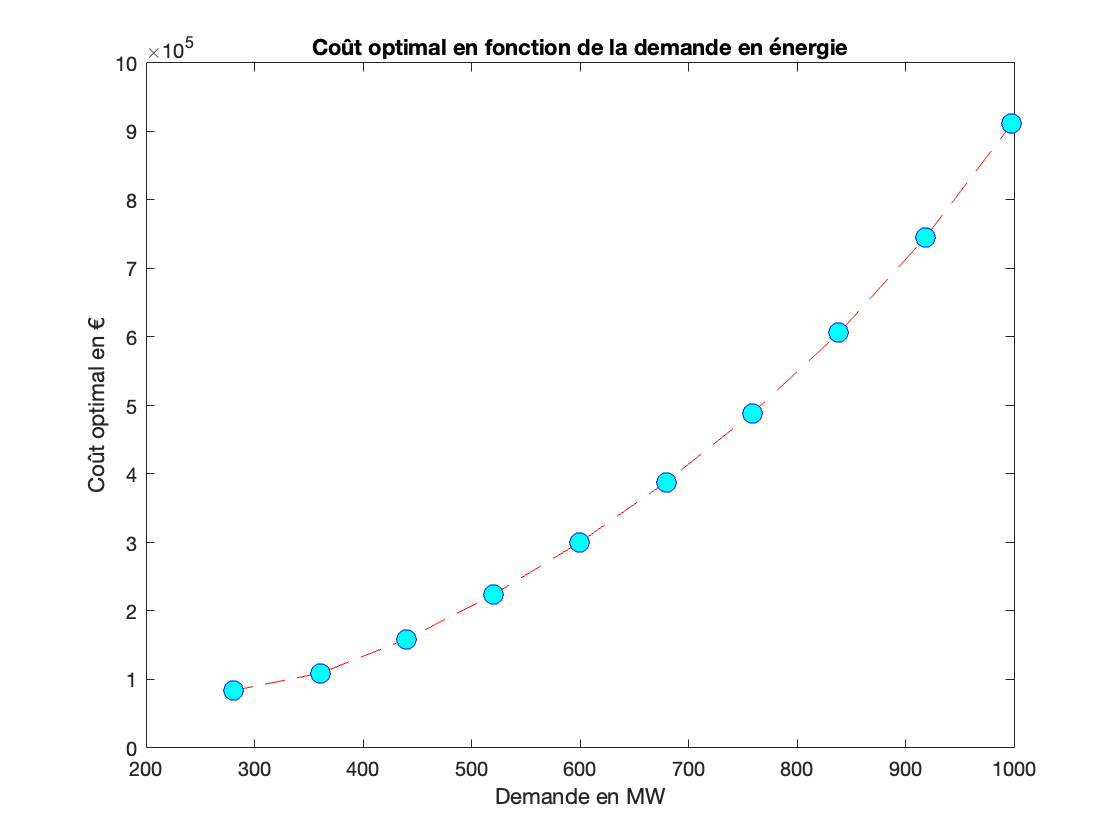

plot(Demandes1,C,'--ro', ...
    'MarkerSize',10, ...
    'MarkerEdgeColor','b', ...
    'MarkerFaceColor','c');
title('Coût optimal en fonction de la demande en énergie')
ylabel('Coût optimal en €')
xlabel('Demande en MW')

            **Evolution des puissances des centrales en fonction de la demande :**

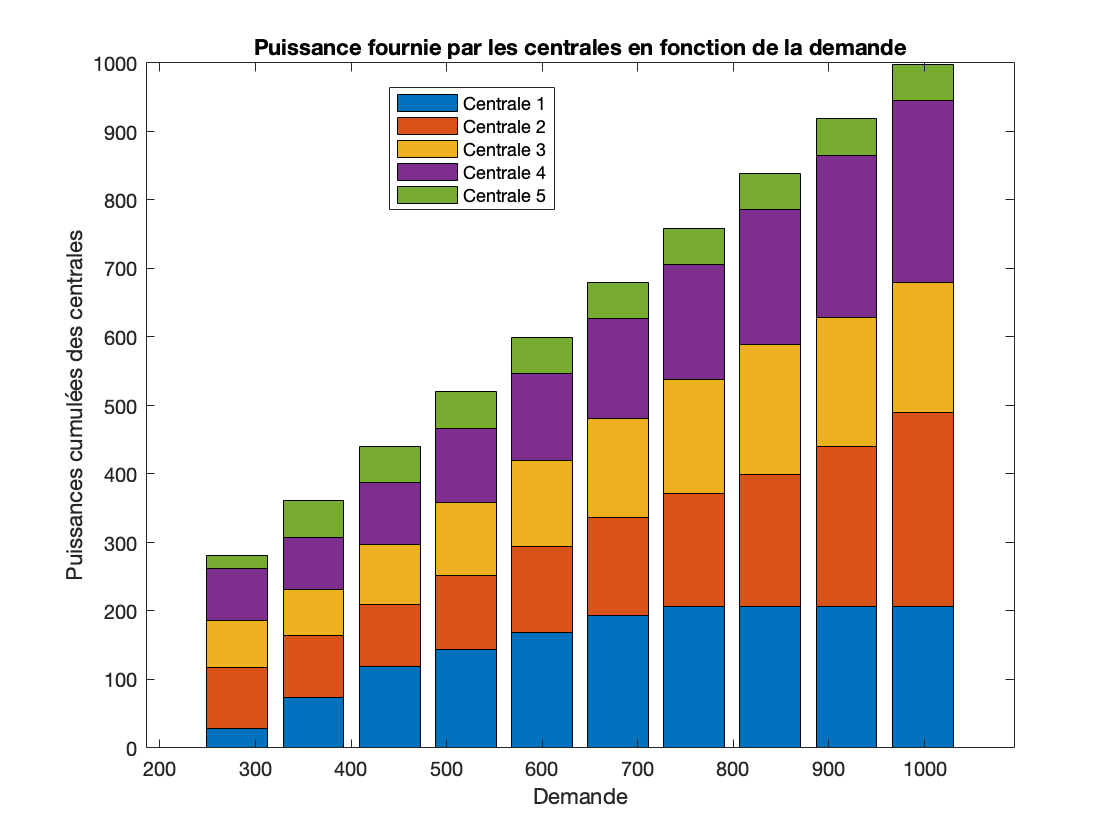

bar(Demandes1, P','stacked')
xlabel('Demande')
ylabel('Puissances cumulées des centrales')
title('Puissance fournie par les centrales en fonction de la demande')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location','best')

## Partie 2

  2.1 Définition de la fonction objectif

% variables : puissances fournies par les centrales en MW
% fonction objectif ==> somme des Ci(Pi) pour i allant de 1 à 5 
fun2 = @(x) (x.^2)*M2(:,1) + x*M2(:,2) + sum(M2(:,3));

    2.2 Définition des contraintes

%contraintes linéaires inégalités 
Aineq2=[];
Bineq2=[];
%contraintes linéaires égalités 
Aeq2=ones(1,N);
Beq2=[Demandes2];

%A nouveau, on prend l'hypothèse que l'on fournit exactement la puissance
%demandée.

%Dans cette partie aussi, on remarque qu'aucune autre contrainte que les bornes
%et la demande n'est imposée aux puissances délivrées

    2.3 Définition des bornes 

%Vecteurs des bornes inférieures : Pmin
lb2=Pmin;
%Vecteur des bornes supérieures : Pmax
ub2=Pmax;

    2.4 Solveur : fmincon

%On utilise fmincon car la fonction objectif est non linéaire et problème soumis à des contraintes.

%Initialisation 
%Idem à partie 1
x0= [Pmin'+1];

%Solveur
option=optimoptions('fmincon','display','iter');
[xsol2, fval2, flag2, output2]=fmincon(fun2, x0, Aineq2,Bineq2, Aeq2, Beq2, Pmin, Pmax,'', option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.692630e+03    1.140e+02    1.021e+01
    1      12    3.666501e+03    1.169e+01    7.559e+00    5.692e+01
    2      18    3.661257e+03    1.066e+01    5.078e+00    1.366e+00
    3      24    3.639814e+03    4.040e+00    2.586e+00    8.935e+00
    4      30    3.660502e+03    1.066e+00    2.461e+00    4.893e+00
    5      36    3.655562e+03    0.000e+00    5.296e-01    1.225e+01
    6      42    3.655171e+03    0.000e+00    4.030e-01    7.883e-01
    7      48    3.654247e+03    0.000e+00    1.758e-01    3.337e+00
    8      54    3.654175e+03    0.000e+00    6.114e-02    7.155e-01
    9      60    3.654169e+03    0.000e+00    4.327e-03    2.075e-01
   10      66    3.654169e+03    5.684e-14    2.504e-04    1.999e-02
   11      72    3.654169e+03    0.000e+00    6.505e-06    1.552e-03



%On cherche l'optimum pour la première fonction objectif i.e le critère
%économique, pour pouvoir comparer les 2 résultats par la suite.
[xsol2bis, fval2bis, flag2bis, output2bis]=fmincon(fun1, x0, Aineq2,Bineq2, Aeq2, Beq2, Pmin, Pmax,'', option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    8.635755e+04    1.140e+02    2.862e+02
    1      12    8.980487e+04    9.448e+01    2.107e+02    1.559e+01
    2      18    1.192574e+05    3.290e+01    2.397e+02    6.876e+01
    3      24    1.198767e+05    1.908e+01    1.316e+02    3.038e+01
    4      30    1.199493e+05    1.892e+01    9.967e+01    1.382e-01
    5      36    1.231243e+05    1.362e+01    9.925e+01    5.146e+00
    6      42    1.321833e+05    0.000e+00    1.376e+02    2.006e+01
    7      48    1.314744e+05    0.000e+00    2.462e+01    1.276e+01
    8      54    1.314577e+05    0.000e+00    1.354e+01    1.674e+00
    9      61    1.314553e+05    0.000e+00    1.097e+01    8.821e-01
   10      67    1.314550e+05    0.000e+00    2.585e-01    2.855e-01
   11      73    1.314550e+05    0.000e+00    7.337e-04    1.299e-02



    2.5 Affichage des résultats 

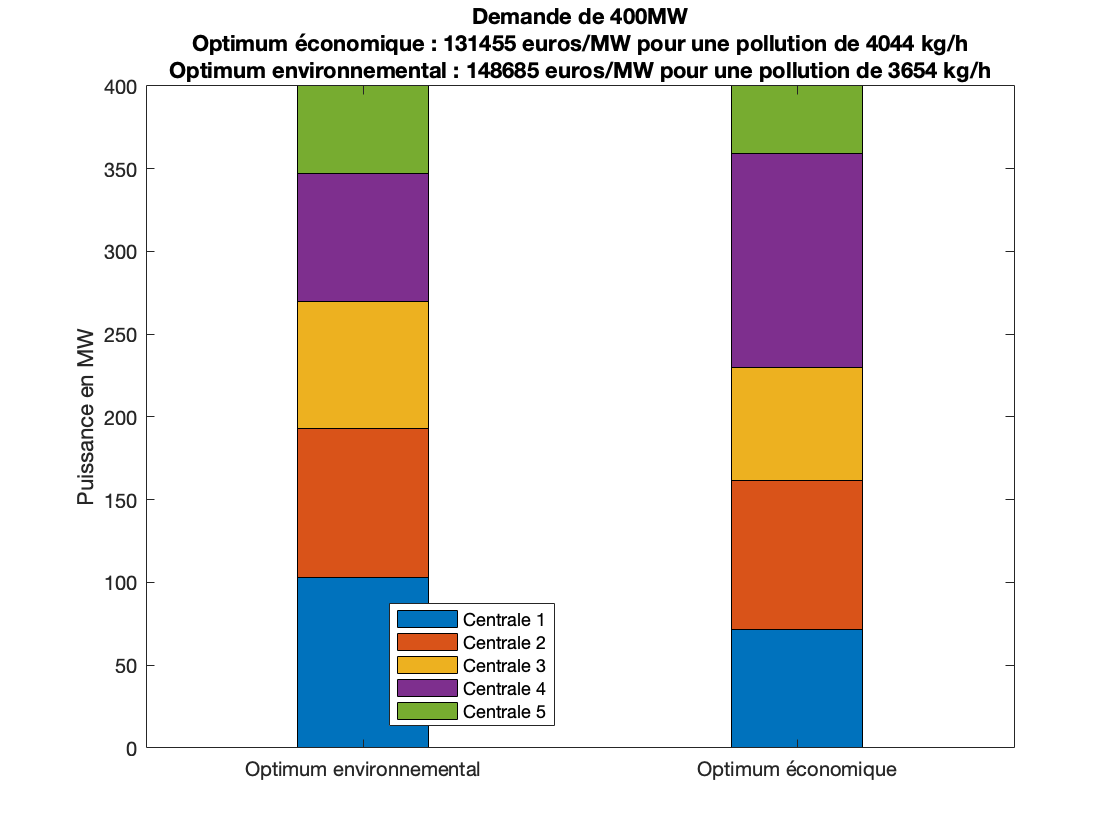

cat = categorical([{'Optimum économique'}, {'Optimum environnemental'}]);
bar(cat,[xsol2;xsol2bis],0.3,'stacked')
ylabel('Puissance en MW')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Demande de 400MW\nOptimum économique : %3.0f euros pour une pollution de %4.0f kg/h\nOptimum environnemental : %3.0f euros pour une pollution de %4.0f kg/h',...
    fval2bis,fun2(xsol2bis),fun1(xsol2),fval2))

Observation : Sans surprise, la résolution via l'optimum économique implique une plus grande pollution que celle trouvée pour l'optimum environnemental, qui lui, engendre des coûts plus importants. 

Il est intéressant de noter la différence de prix qui est de 17 230€, pour une économie de plus de 390kg/h de polluants rejetés. 

Dans une considération environnementale et qualité, il semblerait cette augmentation du coût de production de 11% apparaîtrait nécessaire. Dans la réalité, l'engagement serait-il pris par un industriel ? Pourrait-il se le permettre financièrement parlant ? 

## Partie 3

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

## Annexe : aides pour les graphiques

Ci dessous des codes qui peut vous inspirer pour le tracé de graphiqes. Remerciements à Mathieu Milhé.

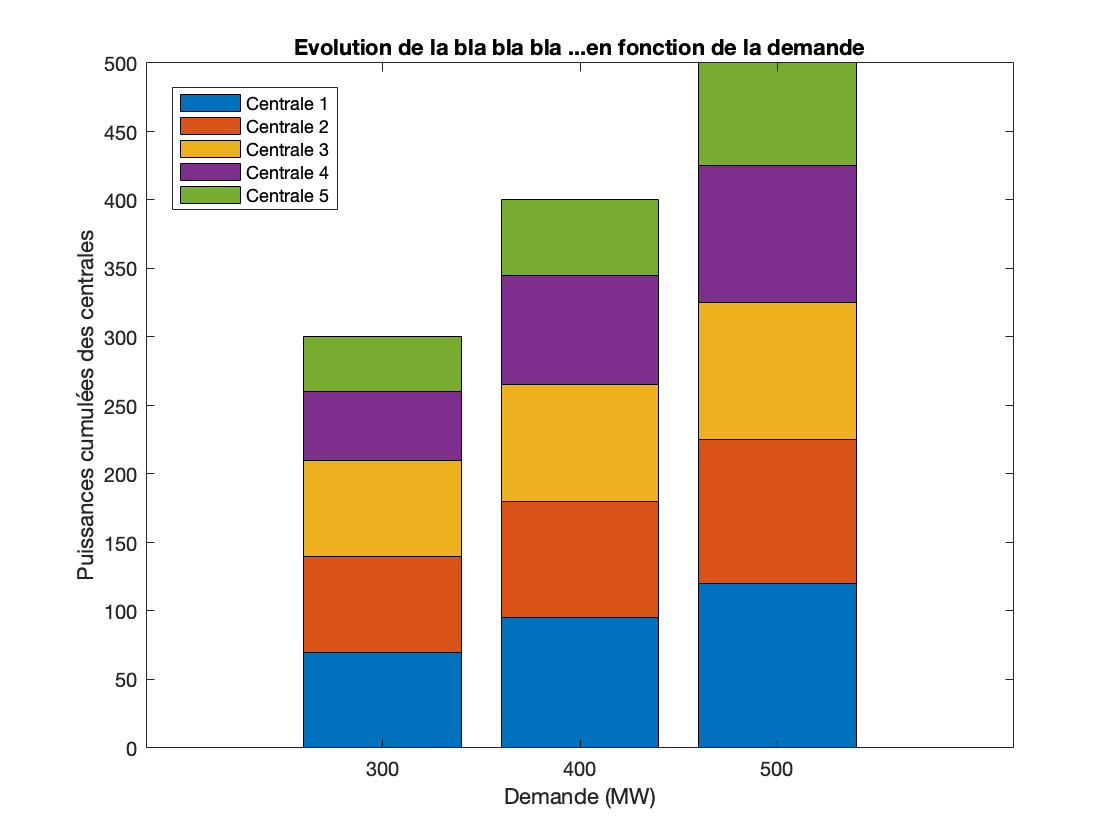

% exemple 1 (valeurs numériques aléatoires choisies)
Demande = 300:100:500;
P2=[70 95 120
   70 85 105
   70 85 100
   50 80 100
   40 55 75];

figure
bar(Demande,P2,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la bla bla bla ...en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

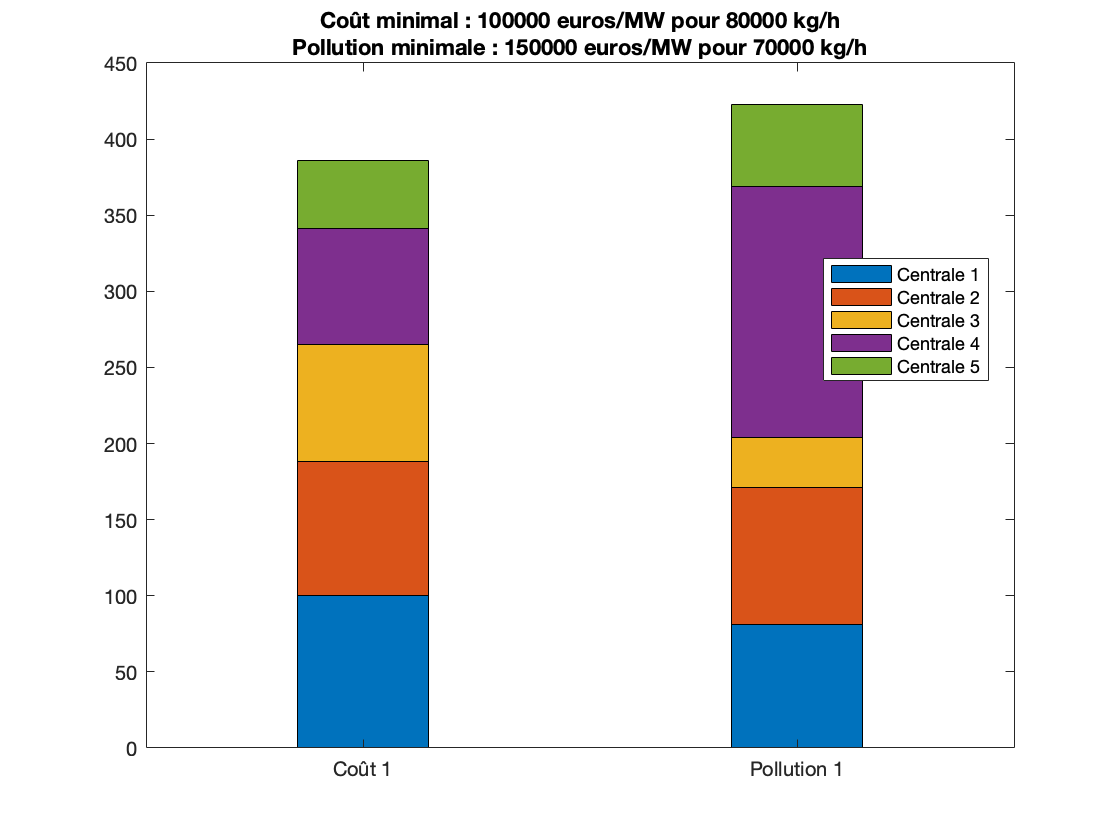

% exemple 2 (valeurs numériques aléatoires choisies)
x = categorical([{'Coût 1'}, {'Pollution 1'}]);
P1 = [100 88 77 76 45];
Q = [81 90 33 165 54];
C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
bar(x,[P1;Q],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
    C1,Pol1,C2,Pol2))

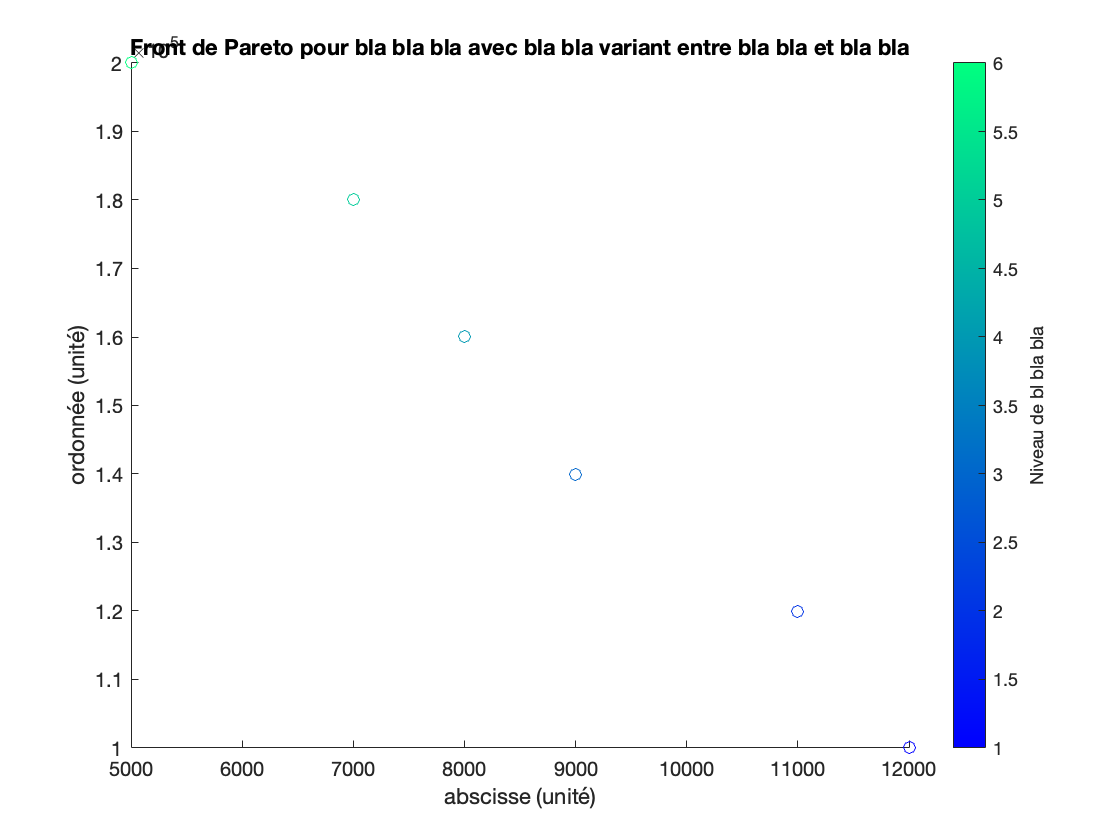

% exemple 3 (valeurs numériques aléatoires choisies)
X=1e5:0.2e5:2e5;
Y=[12 11 9 8 7 5].*1e3;
Z=1:6;
scatter(Y,X,[],Z)
colormap winter
c = colorbar;
c.Label.String = 'Niveau de bl bla bla';
xlabel('abscisse (unité)')
ylabel('ordonnée (unité)')
title('Front de Pareto pour bla bla bla avec bla bla variant entre bla bla et bla bla')